% MATLAB Script for Audio DSP System with Pre-Recorded MP3 Input

%% Initialization
clc;
clear;
close all;

% Declare global variables
global Fs inputSignal gainBands delayTime feedback poles zerosList freqBands;

% Load the pre-recorded MP3 file
try
    [inputSignal, Fs] = audioread('record.mp3'); % Ensure 'record.mp3' is in the same directory
    disp(['Loaded MP3 File: Signal Size = ', num2str(size(inputSignal)), ', Fs = ', num2str(Fs)]);
catch
    error('Failed to load MP3 file. Ensure the file exists and is a valid audio file.');
end

Loaded MP3 File: Signal Size = 196464       1, Fs = 48000



% Validate the sampling rate
if isempty(Fs) || ~isscalar(Fs) || ~isfinite(Fs) || Fs <= 0
    error('Invalid sampling rate (Fs). Ensure Fs is a positive finite scalar.');
end

% Convert stereo to mono if necessary
if size(inputSignal, 2) == 2
    inputSignal = mean(inputSignal, 2); % Convert to mono
end

% Check if the signal is valid
if isempty(inputSignal) || ~any(inputSignal)
    error('The input signal is empty or contains no audible data.');
end

% Detect and trim leading silence
threshold = max(0.001, 0.01 * max(abs(inputSignal))); % Silence threshold
nonSilentIndices = find(abs(inputSignal) > threshold); % Find non-silent indices
if isempty(nonSilentIndices)
    error('The input signal contains only silence. Cannot process.');
end
inputSignal = inputSignal(min(nonSilentIndices):end); % Trim leading silence

% Normalize the input signal
inputSignal = inputSignal / max(abs(inputSignal));

% Debug after trimming silence
disp(['Debug after trimming silence: Signal Length = ', num2str(length(inputSignal))]);

Debug after trimming silence: Signal Length = 194179


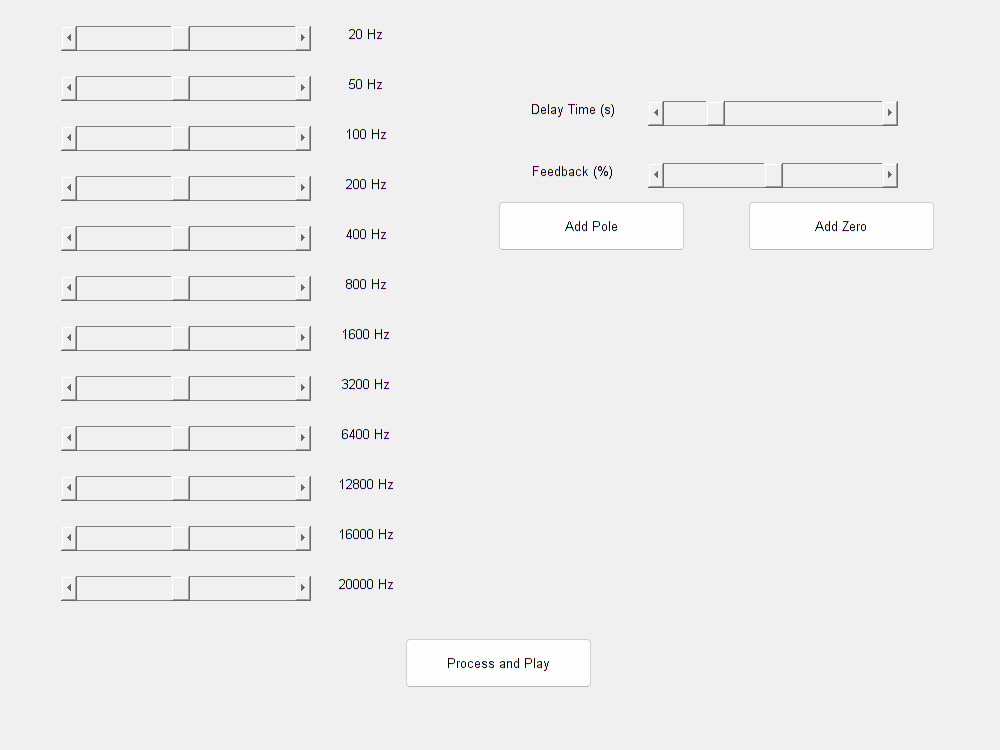


% Initialize global variables
gainBands = ones(1, 12); % Initial gain (0 dB)
delayTime = 0.5; % seconds
feedback = 0.5; % 50%
poles = [];
zerosList = []; % Renamed from 'zeros' to 'zerosList' to avoid conflict
freqBands = [20, 50, 100, 200, 400, 800, 1600, 3200, 6400, 12800, 16000, 20000];

%% User Interface
% Create a GUI for interaction
figure('Name', 'Audio DSP System', 'Position', [100, 100, 800, 600]);

% Equalizer sliders
for i = 1:length(freqBands)
    uicontrol('Style', 'slider', ...
        'Min', 0.1, 'Max', 2, 'Value', 1, ...
        'Position', [50, 600 - 40 * i, 200, 20], ...
        'Callback', @(src, event) updateEqualizer(i, src.Value));
    uicontrol('Style', 'text', ...
        'Position', [260, 600 - 40 * i, 70, 20], ...
        'String', sprintf('%d Hz', freqBands(i)));
end

% Echo controls
uicontrol('Style', 'text', 'Position', [400, 500, 120, 20], 'String', 'Delay Time (s)');
uicontrol('Style', 'slider', 'Min', 0.1, 'Max', 2, 'Value', delayTime, ...
    'Position', [520, 500, 200, 20], ...
    'Callback', @(src, event) updateEcho('delayTime', src.Value));

uicontrol('Style', 'text', 'Position', [400, 450, 120, 20], 'String', 'Feedback (%)');
uicontrol('Style', 'slider', 'Min', 0, 'Max', 1, 'Value', feedback, ...
    'Position', [520, 450, 200, 20], ...
    'Callback', @(src, event) updateEcho('feedback', src.Value));

% Filter design controls
uicontrol('Style', 'pushbutton', 'Position', [400, 400, 150, 40], ...
    'String', 'Add Pole', 'Callback', @(src, event) addPole());
uicontrol('Style', 'pushbutton', 'Position', [600, 400, 150, 40], ...
    'String', 'Add Zero', 'Callback', @(src, event) addZero());

% Play Button
uicontrol('Style', 'pushbutton', 'Position', [325, 50, 150, 40], ...
    'String', 'Process and Play', 'Callback', @(src, event) processAndPlay());


%% DSP Functions

% Update Equalizer gains

function updateEqualizer(band, value)
    global gainBands;
    gainBands(band) = value;
end

% Update Echo parameters
function updateEcho(param, value)
    global delayTime feedback;
    if strcmp(param, 'delayTime')
        delayTime = value;
    elseif strcmp(param, 'feedback')
        feedback = value;
    end
end

% Add a pole to the filter
function addPole()
    global poles;
    poles = [poles; randn + 1i * randn]; % Random pole for demo
end

% Add a zero to the filter
function addZero()
    global zerosList;
    zerosList = [zerosList; randn + 1i * randn]; % Random zero for demo
end

% Process and play the pre-recorded audio
function processAndPlay()
    global inputSignal Fs gainBands freqBands delayTime feedback poles zerosList;
    
    % Validate the sampling rate
    if isempty(Fs) || ~isscalar(Fs) || ~isfinite(Fs) || Fs <= 0
        warning('Invalid sampling rate (Fs). Setting default value of 44100 Hz.');
        Fs = 44100; % Default sampling rate
    end

    % Apply DSP operations
    processedSignal = inputSignal; % Start with the input signal

    % Apply equalizer
    processedSignal = equalizeAudio(processedSignal, gainBands, Fs, freqBands);

    % Apply echo
    processedSignal = applyEcho(processedSignal, Fs, delayTime, feedback);

    % Apply filter
    processedSignal = applyFilter(processedSignal, poles, zerosList);

    % Check processed signal
    if isempty(processedSignal) || all(processedSignal == 0)
        error('Processed signal is empty or silent. Check DSP functions for errors.');
    end

    % Normalize the processed signal
    processedSignal = processedSignal / max(abs(processedSignal));

    % Play the processed audio
    audioOut = audioplayer(processedSignal, Fs);
    playblocking(audioOut);
end

% Equalizer implementation
function output = equalizeAudio(input, gainBands, Fs, freqBands)
    output = zeros(size(input));
    for i = 1:length(freqBands)
        % Valid frequency range
        lowerCutoff = max(20, freqBands(i) * 0.8);
        upperCutoff = min(Fs / 2 - 1, freqBands(i) * 1.2);

        % Skip invalid ranges
        if lowerCutoff >= upperCutoff
            warning('Invalid filter range for band %d. Skipping...', i);
            continue;
        end

        % Design bandpass filter
        try
            bpFilter = designfilt('bandpassiir', ...
                'FilterOrder', 4, ...
                'HalfPowerFrequency1', lowerCutoff, ...
                'HalfPowerFrequency2', upperCutoff, ...
                'SampleRate', Fs);
            filteredSignal = filter(bpFilter, input);
            output = output + gainBands(i) * filteredSignal;
        catch ME
            warning('Error in filter design for band %d: %s', i, ME.message);
        end
    end
end

% Echo implementation
function output = applyEcho(input, Fs, delayTime, feedback)
    delaySamples = round(delayTime * Fs);
    if delaySamples < 1
        warning('Delay time too short. Skipping echo.');
        output = input;
        return;
    end
    buffer = zeros(delaySamples, 1);
    output = zeros(size(input));
    for n = 1:length(input)
        echoSample = buffer(1);
        output(n) = input(n) + feedback * echoSample;
        buffer = [input(n); buffer(1:end-1)];
    end
end

% Filter design implementation
function output = applyFilter(input, poles, zerosList)
    if isempty(poles) && isempty(zerosList)
        output = input; % No filter applied
        return;
    end
    try
        [b, a] = zp2tf(zerosList, poles, 1);
        output = filter(b, a, input);
    catch ME
        warning('Error in custom filter: %s', ME.message);
        output = input;
    end
end
